# Lab05 - Covariance and Correlation

#### **Please watch following videos first**

#### [**https://www.youtube.com/watch?v=qtaqvPAeEJY&t=19s**](https://www.youtube.com/watch?v=qtaqvPAeEJY&t=19s)

#### [**https://www.youtube.com/watch?v=xZ_z8KWkhXE&t=3s**](https://www.youtube.com/watch?v=xZ_z8KWkhXE&t=3s)

#### **Create two vectors that's correlation value obviously 1**

x1=1:10

x1 =      1     2     3     4     5     6     7     8     9    10


y1=10:10:100

y1 =     10    20    30    40    50    60    70    80    90   100


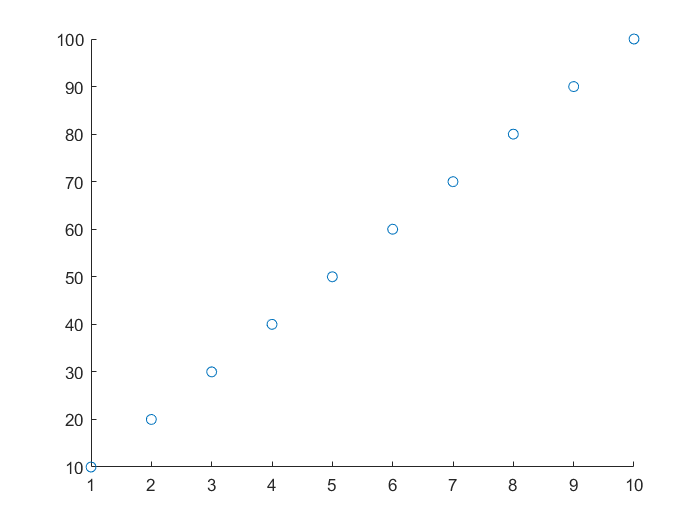

scatter(x1,y1)


cov1=cov(x1,y1)

cov1 =     9.1667   91.6667
   91.6667  916.6667


corr1=corrcoef(x1,y1)

corr1 =      1     1
     1     1


corr11=corr(x1',y1')

corr11 = 1

#### **Create two vectors that's correlation value obviously -1**

x2=1:10

x2 =      1     2     3     4     5     6     7     8     9    10


y2=100:-10:10

y2 =    100    90    80    70    60    50    40    30    20    10


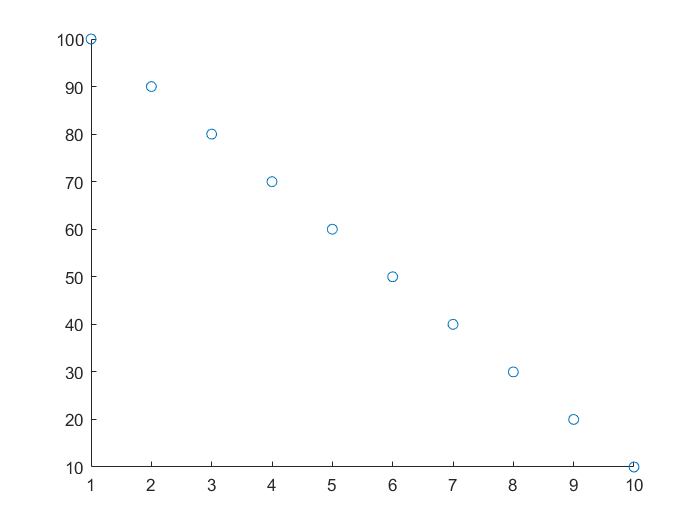

scatter(x2,y2)


cov2=cov(x2,y2)

cov2 =     9.1667  -91.6667
  -91.6667  916.6667


corr2=corr(x2',y2')

corr2 = -1

#### Let's look for correlation between Weight and Horsepower

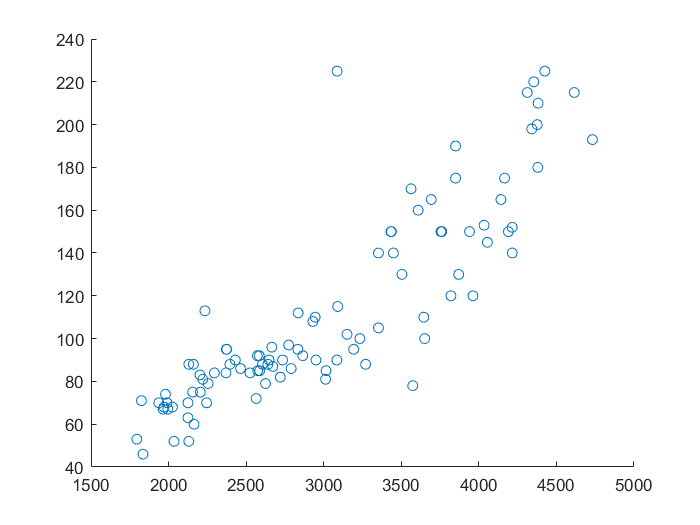

clear
clc
load carsmall.mat
scatter(Weight,Horsepower)

cov3=cov(Weight,Horsepower)

cov3 = 	1.0e+05 *

    6.5119       NaN
       NaN       NaN



Horsepower(isnan(Horsepower))=nanmean(Horsepower);
cov3=cov(Weight,Horsepower)

cov3 = 	1.0e+05 *

    6.5119    0.3192
    0.3192    0.0205


corr3=corr(Weight,Horsepower)

corr3 = 0.8733

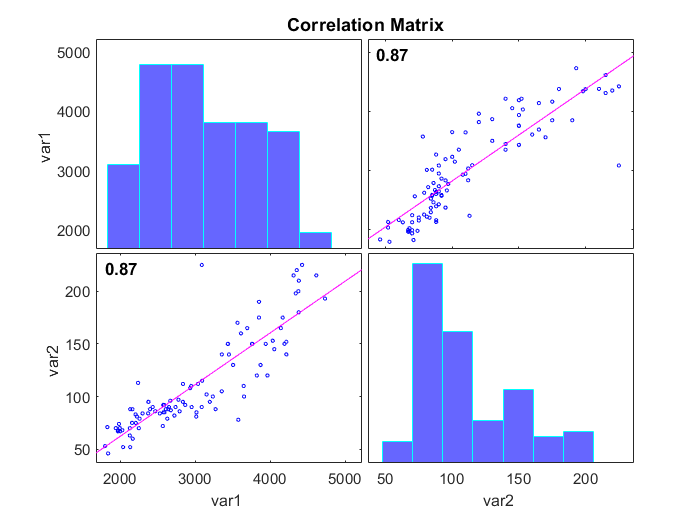

corrplot([Weight Horsepower])

#### Let's look for correlation between Weight and Horsepower

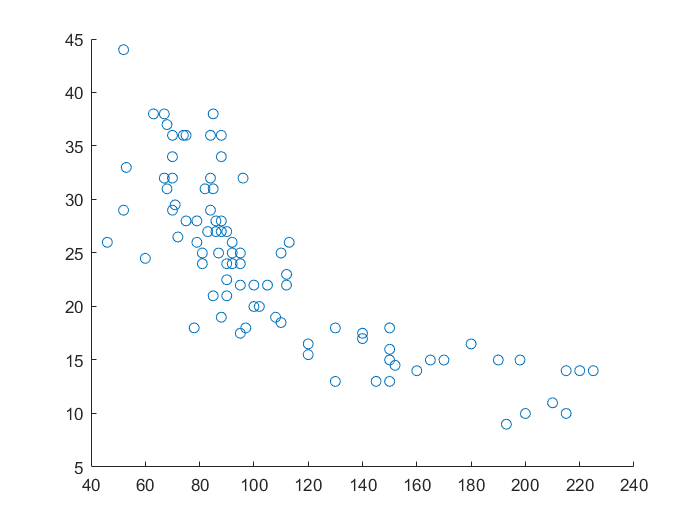

scatter(Horsepower,MPG)

cov4=cov(Horsepower,MPG)

cov4 = 	1.0e+03 *

    2.0518       NaN
       NaN       NaN


cov41=nancov(Horsepower,MPG)

cov41 = 	1.0e+03 *

    2.0350   -0.2910
   -0.2910    0.0646


corr4=corr(Horsepower,MPG,"rows","complete")

corr4 = -0.8028

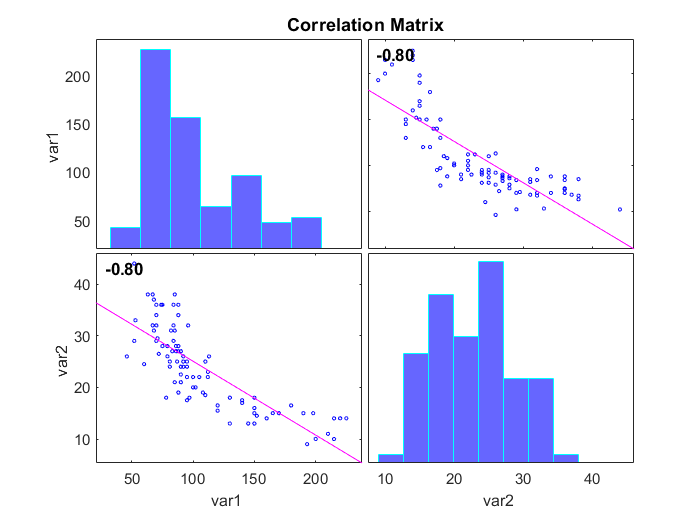

corrplot([Horsepower MPG])